**Data**

x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];

**Plot data**

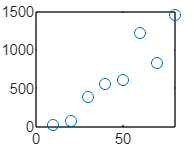

plot(x,y,'o')

**Calculate polynomial regression using  **`polyfit`**  function**

p = polyfit(x,y,2)

p =     0.0372   16.1220 -178.4821


%get slope and y intercept
% a1 and a0

**Plot data and the best fitted curve**

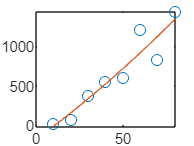

xx = 10 : 0.1 : 80;

yy = polyval(p, xx);

plot(x,y,'o',xx,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum(y-a(2)-a(1)*x-a(3)*x.^2) ^ 2

Sr = 8.3527e+09

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 1.8083e+06

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = -4.6181e+03

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(Sr/(length(x)-length(a)))

syx = 4.0872e+04

**Predict the value of y for the given x**

xtest = 6;
predict_y = polyval(p,xtest)

predict_y = -80.4107